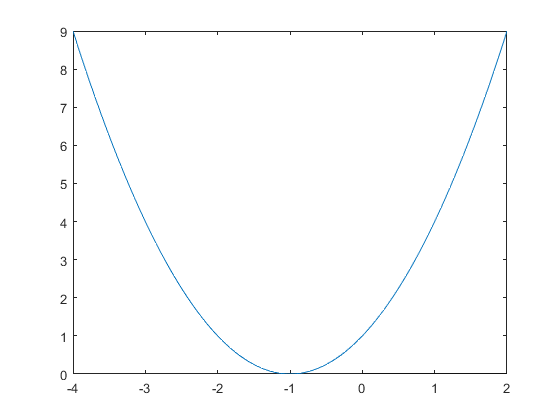

f=@(x) (x+1).^2; %Funzione
df=@(x) 2*(x+1); %Derivata prima
%Grafico
x_mesh=linspace(-4,2);%Rete di punti che ci servirà per produrre il grafico
plot(x_mesh,f(x_mesh)) %Questa sarà l'approssimazione del grafico
hold on;
plot([0,2],[0,0],"k") %Asse delle ascisse: plot di ascissa dei punti [0,2] e ordinata dei punti [0,0]


x_n_m=.45;
tol=1e-7;
nitmax=100;

format longe;

[x,nit,res2] = Bextra_newton_mod(f,df,x_n_m,tol,nitmax)

0	 0.450000000000000	 +2.1e+00
1	 -0.275000000000000	 +5.3e-01
2	 -0.637500000000000	 +1.3e-01
3	 -0.818750000000000	 +3.3e-02
4	 -0.909375000000000	 +8.2e-03
5	 -0.954687500000000	 +2.1e-03
6	 -0.977343750000000	 +5.1e-04
7	 -0.988671875000000	 +1.3e-04
8	 -0.994335937500000	 +3.2e-05
9	 -0.997167968750000	 +8.0e-06
10	 -0.998583984375000	 +2.0e-06
11	 -0.999291992187500	 +5.0e-07
12	 -0.999645996093750	 +1.3e-07
13	 -0.999822998046875	 +3.1e-08
14	 -0.999911499023437	 +7.8e-09
15	 -0.999955749511719	 +2.0e-09
16	 -0.999977874755859	 +4.9e-10
17	 -0.999988937377930	 +1.2e-10
18	 -0.999994468688965	 +3.1e-11
19	 -0.999997234344482	 +7.6e-12
20	 -0.999998617172241	 +1.9e-12
21	 -0.999999308586121	 +4.8e-13
22	 -0.999999654293060	 +1.2e-13
23	 -0.999999827146530	 +3.0e-14
24	 -0.999999913573265	 +7.5e-15


x =     -9.999999135732651e-01


nit =     24


res2 =      2.102500000000000e+00     5.256249999999998e-01     1.314062500000000e-01     3.285156250000001e-02     8.212890624999991e-03     2.053222656249998e-03     5.133056640625020e-04     1.283264160156255e-04     3.208160400390700e-05     8.020401000977066e-06     2.005100250244266e-06     5.012750625610666e-07     1.253187656402273e-07     3.132969141005684e-08     7.832422852524034e-09     1.958105713131009e-09     4.895264282802957e-10     1.223816070700739e-10     3.059540176813259e-11     7.648850442033147e-12     1.912212610354762e-12     4.780531525886905e-13     1.195132881855538e-13     2.987832204638845e-14     7.469580502001817e-15


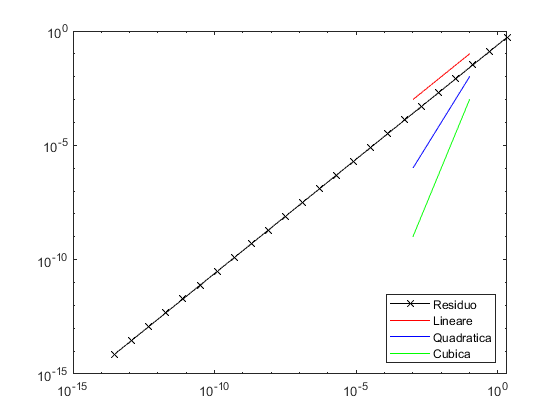


figure;
loglog(abs(res2(1:end-1)),abs(res2(2:end)),"x-k") %Vettore dei residui
hold on;
loglog([1e-1,1e-3],[1e-1,1e-3], "r") %Convergenza lineare
loglog([1e-1,1e-3],[1e-2,1e-6], "b") %Convergenza quadratica
loglog([1e-1,1e-3],[1e-3,1e-9], "g") %Convergenza cubica
legend("Residuo","Lineare", "Quadratica","Cubica","location","southeast");